syms t

% hyperparameters
protected_zone = 2.5;    % zone of protection
v = 5;
omega = 1;
phi = pi/2;
init_state = [15; -15];

v1 = v;
v2 = v;
omega_1 = omega;
omega_2 = omega;

% equation
x_r_dot_q1 = -v1 + v2*cos(phi);
y_r_dot_q1 = v2*sin(phi);
phi_r_dot_q1 = 0;
state_q1_dot = [x_r_dot_q1; y_r_dot_q1]

state_q1_dot =     -5
     5


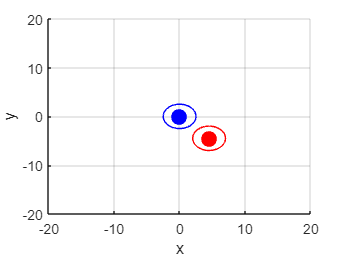


% solutions of given differential equation
x_r_q2 = -5 * cos(t) - 5 * sin(t) + 5;
y_r_q2 = -5 * cos(t) + 5 * sin(t) + 5;

% hyperparameter of simulation
t_switch_12 = 2.3;
t_switch_23 = pi/omega;
dt = 0.1;
sim_pause = 0.3; 
v_rel = [-v; v];


% plot
figure;
grid on
hold on
xlabel('x');
ylabel('y');
xlim([-20, 20])
ylim([-20, 20])


% prepare mooving plot
theta = linspace(0, 2*pi, 100);
x1_circle = protected_zone * cos(theta);
y1_circle = protected_zone * sin(theta);
x2_circle = protected_zone * cos(theta) + init_state(1);
y2_circle = protected_zone * sin(theta) + init_state(2);

a1 = plot(0, 0, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
a2 = plot(init_state(1), init_state(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
s1 = plot(x1_circle, y1_circle, 'b');
s2 = plot(x2_circle + init_state(1), y2_circle + + init_state(2), 'r');


iteration_12 = t_switch_12/dt;

for t1=1:iteration_12
    
    set(a2, 'XData', init_state(1), 'YData', init_state(2));
    set(s2, 'XData', x2_circle, 'YData', y2_circle );

    init_state = init_state + v_rel*dt;
    x2_circle = x2_circle + v_rel(1)*dt;
    y2_circle = y2_circle + v_rel(2)*dt;

    pause(sim_pause)
end